clear; close all, clc
% this is the true cessna 182
% note that insufficiently many lateral flap sections exist. at least 3
% spanwise flap sections are recomended per wing for desired lateral
% response.

% this is cals model
% currently roughly trimmed

## Define the simulation parameters

dt = .1; % time step (seconds)
t_total = 10 % total simulation time (seconds)

t_total = 10

time = [0:dt:t_total]';
angle = 5; % perturbed deflection (degrees)

disable_PAH = false; % use rigid flap?

k_command = .2; % comanded value of spring stiffness (N/m)
c_r_command = .05; % comanded value of rate damping ()
c_c_command = .005; % commanded value of coulomb damping ()
delt_0_command = deg2rad(5); % comanded value of deflection (rad)

I_flap = .9; % moment of inertia of flap about hinge line (kg*m^4)

% Dryden turbulence parameters (modify as needed)
altitude = convlength(46000,"ft","m");     % Initial altitude (m)
windspeed_20ft = 15;   % Wind speed at 20 ft (m/s)
turbulence_intensity = 'severe'; % 'light', 'moderate', or 'severe'

% Generate Dryden gust velocities
[ug, vg, wg] = generate_dryden_gust(time, altitude, windspeed_20ft, turbulence_intensity);

% these are good if the initial flap angle is zero
x_0 = [k_command, c_r_command, c_c_command, delt_0_command, I_flap];
x_0 = [.2, .05, .0005, .087266, .9]; % pretty good values - optimal for the c310
x_0 = [-0.0518, 43.6289, 0.0005, 85.1409, 1.4451]; % optimal over 20 second window (very good)
x_0 = [0.6773, 11.2789, 0.0004, -2.0731, 16.5946]; % less optimal over 20 second window but positive
% x_0 = [-6.8349, 14.5220, 0.0004, 0.7776, 7.4999] % optimal over 150 seconds 

## run base case - no PAH

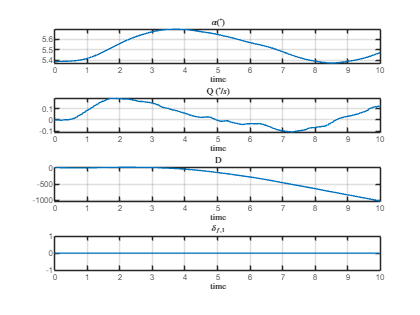

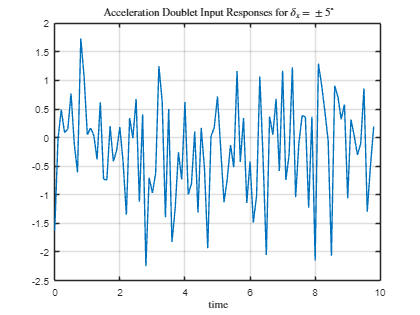

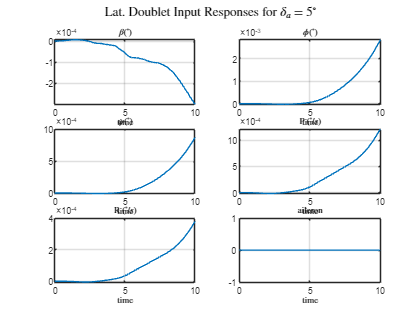

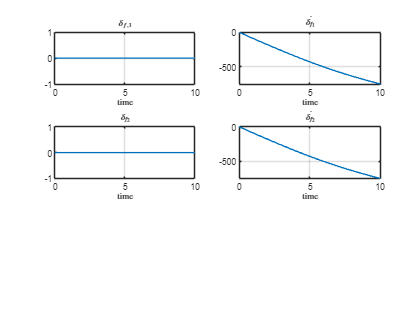

[y_all, time] = simulation(dt, t_total, angle, ug,vg,wg, k_command, c_r_command, c_c_command, delt_0_command, I_flap, true);
plot_6dof_results(y_all, time, angle);

f = objective_function(x_0, dt, t_total, angle, ug,vg,wg, true)

f = 0.2642


% % sys = ssest([time; y_all(1)],2)
% sys = ssest([time(1:end-2); diff(diff(y_all(12)))],2)
% frsys = idfrd(sys)
% % bode(frsys)
% figure;
% spectrum(frsys)

## Perform optimization

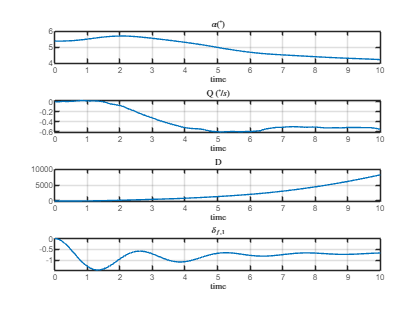

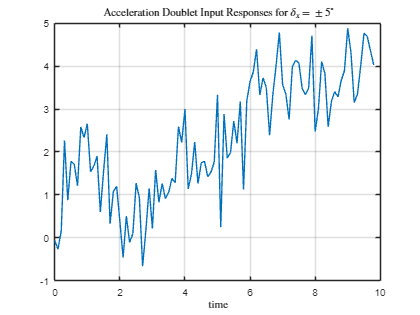

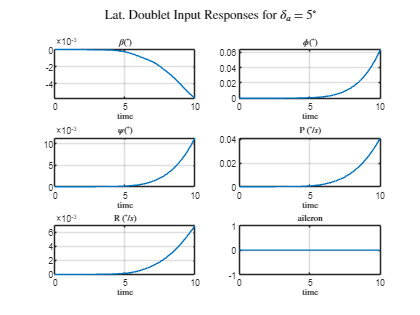

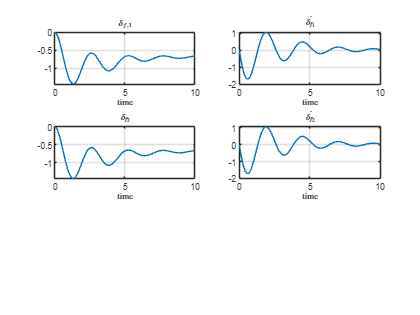

[y_all, time] = simulation(dt, t_total, angle, ug,vg,wg, x_0(1), x_0(2), x_0(3), x_0(4), x_0(5), false);
plot_6dof_results(y_all, time, angle);

f = objective_function(x_0, dt, t_total, angle, ug,vg,wg, false)

f = 0.2660


% Define the objective function
obv_fun = @(x) objective_function(x, dt, t_total, angle,  ug,vg,wg, false);

% Define the initial design variables

% Define the bounds for the design variables
% lb = [0, 0, .004, -1e1, 1e-6];
% ub = [1e1, 1e1, 1e1, 1e1, 1e1];
lb = [-5e1, 0, .0004, -1e2, 1e-9];
ub = [5e1, 5e1, .0005, 1e2, 5e1];


% GA parameters - origianl
pop_size = 3; % Population size
max_generations = 4; % Number of generations
mutation_rate = 0.1; % Mutation rate
elite_size = 1; % Number of elite members to retain

% new GA paramters
pop_size = 50; % Population size
max_generations = 40; % Number of generations
mutation_rate = 0.3; % Mutation rate
elite_size = 3; % Number of elite members to retain

pop_size = 50; % Population size
max_generations = 20; % Number of generations
mutation_rate = 0.3; % Mutation rate
elite_size = 3; % Number of elite members to retain


% Initialize population
population = repmat(lb, pop_size, 1) + rand(pop_size, numel(lb)) .* repmat(ub - lb, pop_size, 1);

% Main GA loop
for generation = 1:max_generations
    % Evaluate fitness of each individual
    fitness = zeros(pop_size, 1);
    % Generate Dryden gust velocities
    [ug_train, vg_train, wg_train] = generate_dryden_gust(time, altitude, windspeed_20ft, turbulence_intensity);
    parfor i = 1:pop_size
        fitness(i) = objective_function(population(i, :), dt, t_total, angle, ug_train, vg_train, wg_train, disable_PAH); % printing this is good to track progress
    end
    
    % Elitist selection
    [sorted_fitness, sorted_indices] = sort(fitness);
    elite_population = population(sorted_indices(1:elite_size), :);
    
    % Select individuals based on fitness (roulette wheel selection)
    fitness_sum = sum(fitness);
    fitness_prob = fitness / fitness_sum;
    selected_indices = randsample(1:pop_size, pop_size - elite_size, true, fitness_prob);
    selected_population = population(selected_indices, :);
    
    % Apply crossover and mutation
    new_population = selected_population;
    for i = 1:2:(pop_size - elite_size)
        if i+1 > (pop_size - elite_size), break; end
        % Crossover
        crossover_point = randi(numel(lb) - 1);
        new_population(i, crossover_point+1:end) = selected_population(i+1, crossover_point+1:end);
        new_population(i+1, crossover_point+1:end) = selected_population(i, crossover_point+1:end);
        
        % Mutation
        if rand < mutation_rate
            mutation_idx = randi(numel(lb));
            new_population(i, mutation_idx) = lb(mutation_idx) + rand * (ub(mutation_idx) - lb(mutation_idx));
        end
        if rand < mutation_rate
            mutation_idx = randi(numel(lb));
            new_population(i+1, mutation_idx) = lb(mutation_idx) + rand * (ub(mutation_idx) - lb(mutation_idx));
        end
    end
    
    % Update population with elite members
    population = [elite_population; new_population];
    
    % Display progress
    disp(['Generation: ', num2str(generation), ', Best Fitness: ', num2str(min(sorted_fitness))]);
end

Generation: 1, Best Fitness: 0.18323
Generation: 2, Best Fitness: 0.19149
Generation: 3, Best Fitness: 0.1959
Generation: 4, Best Fitness: 0.19102
Generation: 5, Best Fitness: 0.1945
Generation: 6, Best Fitness: 0.18114
Generation: 7, Best Fitness: 0.19729
Generation: 8, Best Fitness: 0.19169
Generation: 9, Best Fitness: 0.1694
Generation: 10, Best Fitness: 0.19142
Generation: 11, Best Fitness: 0.199
Generation: 12, Best Fitness: 0.19837
Generation: 13, Best Fitness: 0.17912
Generation: 14, Best Fitness: 0.19779
Generation: 15, Best Fitness: 0.18163
Generation: 16, Best Fitness: 0.19282
Generation: 17, Best Fitness: 0.17014
Generation: 18, Best Fitness: 0.21014
Generation: 19, Best Fitness: 0.19243
Generation: 20, Best Fitness: 0.1863



% Find the best solution
x_opt = elite_population(1, :);
f_opt = sorted_fitness(1);

% Display the optimal solution
disp('Optimal design variables:'); 

Optimal design variables:


disp(x_opt); 

  -15.5200   27.9713    0.0004  -57.7118   41.6934



disp('Optimal objective function value:');

Optimal objective function value:


disp(f_opt);

    0.1863





% Display the optimal solution
disp('Optimal design variables:'); 

Optimal design variables:


disp(x_opt); disp('Optimal objective function value:');

  -15.5200   27.9713    0.0004  -57.7118   41.6934

Optimal objective function value:


disp(f_opt);

    0.1863



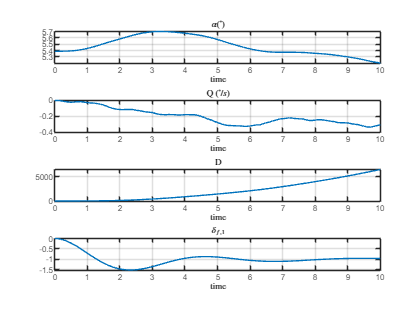

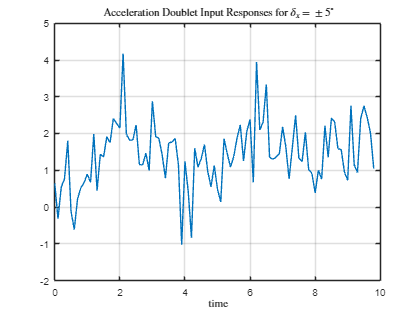

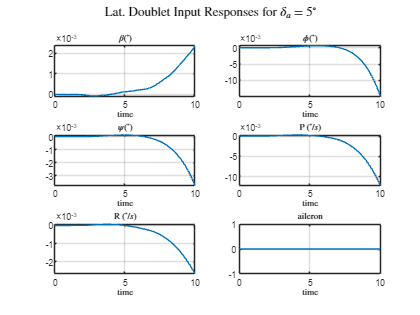

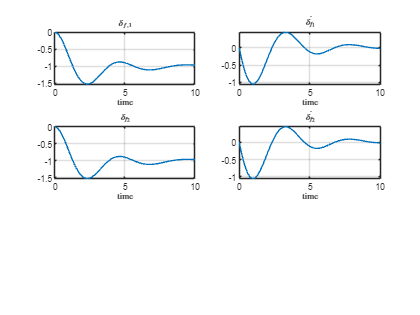


[y_all, time] = simulation(dt, t_total, angle, ug,vg,wg, x_opt(1), x_opt(2), x_opt(3), x_opt(4), x_opt(5), false);
plot_6dof_results(y_all, time, angle);

function [y_all, time] = simulation(dt, t_total, angle, ug,vg,wg, k_command, c_r_command, c_c_command, delt_0_command, I_flap, disable_PAH)
    % define IC and controls
    time = [0:dt:t_total]';
    t_0 = 1;
    t_end = length(time);
    
    %elevator trim angle
    delta_e_trim = deg2rad(-1.3683881539243);
    delta_e_trim = deg2rad(0);
    alpha_trim = deg2rad(5.38766545134696);%+deg2rad(2);


    throttle = zeros(size(time));
    elevator = ones(size(time))* deg2rad(delta_e_trim);
    aileron = zeros(size(time));
    rudder = zeros(size(time));
    % elevator(1/dt:1.5/dt) = ones(size(1/dt:1.5/dt)).*angle.*pi./180 + deg2rad(delta_e_trim);
    %aileron(1/dt:1.5/dt) = ones(size(1/dt:1.5/dt)).*angle.*pi./180;
    
    k = ones(size(time)) .* k_command; % PAH spring const
    c_r = ones(size(time)) .* c_r_command; % rate damping coefficient (N*s/rad^2)
    c_c = ones(size(time)) .* c_c_command; % coulomb damping coefficient (N*s/rad^2)
    delta_0 = zeros(size(time)); % commanded deflection (radians)
    % delta_0 = ones(size(time)) .* delt_0_command; % commanded deflection (radians)
    % colombic damping coefficient (N)pm
    
    %k = k + .03*randn(size(time));
    %delta_0 = delta_0 + .003*randn(size(time));
    
    
    % elevator(1.5/dt:2/dt) = ones(size(1.5/dt:2/dt)).*angle.*-pi./180.;
    % elevator = elevator  + .003*randn(size(elevator));
    VT = zeros(size(time));
    VT(1) = convvel(487.542331889981,"kts","ft/s");
    Alphaest = ones(size(time))*alpha_trim; % if i starrt thisa a number that is not trim then i get the response to an alpha disturbance
    Betaest = zeros(size(time));
    phi = zeros(size(time));
    theta = zeros(size(time));
    theta = ones(size(time))*alpha_trim;
    psi = zeros(size(time));
    P = zeros(size(time));
    Q = zeros(size(time));
    R = zeros(size(time));
    ned = [zeros(size(time)),zeros(size(time)),zeros(size(time))];
    delta_f_1 = 0; % inital flap 1 position
    delta_f_dot_1 = 0; % initial flap 1 rate
    delta_f_2 = 0; % inital flap 2 position
    delta_f_dot_2 = 0; % initial flap 2 rate

    % try this
    % delta_f_1 = delt_0_command; % inital flap 1 position
    % delta_f_dot_1 = 0; % initial flap 1 rate
    % delta_f_2 = delt_0_command; % inital flap 2 position
    % delta_f_dot_2 = 0; % initial flap 2 rate
    
    cv = [throttle,   elevator ,   aileron  ,   rudder, k, c_r, delta_0, c_c];
    X_0 = [VT(1), Alphaest(1), Betaest(1), phi(1), theta(1), psi(1), ...
        P(1), Q(1), R(1), ned(1,1), ned(1,2), -ned(1,3), throttle(t_0), elevator(t_0) , ...
        aileron(t_0) , rudder(t_0),...
        delta_f_1, delta_f_dot_1, delta_f_2, delta_f_dot_2];
    
    y = X_0;
    
    %initialize y_all and t_all with IC as first element
    y_all = zeros([length(t_0:t_end),20]);       t_all = zeros([length(t_0:t_end),1]);
    y_all(1,:) = y;     t_all(1) = time(t_0);       J = 2;
    
    % produce dryden turbulence

    % Dryden turbulence parameters (modify as needed)
    altitude = convlength(46000,"ft","m");     % Initial altitude (m)
    windspeed_20ft = 15;   % Wind speed at 20 ft (m/s)
    turbulence_intensity = 'moderate'; % 'light', 'moderate', or 'severe'
    
    % Generate Dryden gust velocities
    [ug, vg, wg] = generate_dryden_gust(time, altitude, windspeed_20ft, turbulence_intensity);
    %plot(time,convvel([ug; vg; wg], "m/s", "ft/s")); legend(["u_g", "v_g", "w_g"])

    for i = (t_0):(length(time)-1)
        cv1 = cv(i,:); %update control inputs and time span for ODE45 each iteration
    
        % PID controller for the PAH
        %k(demanded)
        gust_velocities = convvel([ug(i), vg(i), wg(i)], "m/s", "ft/s");
    
        tspan = [time(i) time(i+1)];       dt = time(i+1) - time(i);
        [t,y] = ode45(@(t,y) Aether_6DOF(t, y, cv1, gust_velocities, [], I_flap, disable_PAH), tspan, X_0);
        X_0 = y(size(y, 1),:);  % set new IC as ending state
        t_all(J) = t(end);       y_all(J,:) = y(end,:);
        J = J + 1; % indexer for recording y and t
    end
end

function f = objective_function(x, dt, t_total, angle, ug,vg,wg, disable_PAH)
    % unpack x
    k_command = x(1); c_r_command = x(2); c_c_command = x(3); delt_0_command = x(4); I_flap = x(5);

    % run simulation
    %[y_all, time] = simulation(dt, t_total, angle, k_command, c_r_command, c_c_command, delt_0_command, I_flap, disable_PAH);
    [y_all, time] = simulation(dt, t_total, angle, ug,vg,wg, k_command, c_r_command, 0, delt_0_command, I_flap, disable_PAH); % set couloub to 0

    % i dont think i need to do this but ben does it so i will keep it
    %13-16 are elevator alteroion etc.
    var_guid = {'U (ft/s)', '$\alpha (^\circ)$', '$\beta (^\circ)$', '$\phi (^\circ)$' '$\theta (^\circ)$', '$\psi (^\circ)$', 'P ($^\circ / s$)', 'Q ($^\circ / s$)','R ($^\circ / s$)','N' ,'E' ,'D', 'throttle', 'elevator', 'aileron', 'rudder', '$\delta_{f,1}$', '$\dot{\delta_{f_1}}$','$\delta_{f_2}$', '$\dot{\delta_{f_2}}$'};
    for ii = 1:length(var_guid)
        Vname{ii} = y_all(:,ii);
    end

    % we will minimize maximum total acceleration
    f = max(sqrt( diff(diff(Vname{10})).^2 + diff(diff(Vname{11})).^2 + diff(diff(Vname{12})).^2 ));
end

function plot_6dof_results(y_all, time, angle)
    %Convert to deg
    y_all(:,2:end) = y_all(:,2:end)*180/pi;
    
    %13-16 are elevator alteroion etc.
    var_guid = {'U (ft/s)', '$\alpha (^\circ)$', '$\beta (^\circ)$', '$\phi (^\circ)$' '$\theta (^\circ)$', '$\psi (^\circ)$', 'P ($^\circ / s$)', 'Q ($^\circ / s$)','R ($^\circ / s$)','N' ,'E' ,'D', 'throttle', 'elevator', 'aileron', 'rudder', '$\delta_{f,1}$', '$\dot{\delta_{f_1}}$','$\delta_{f_2}$', '$\dot{\delta_{f_2}}$'};
    
    % Plot Longitudinal variables (VT, VT_guid, theta, theta_guid, Q, del_t, del_e)
    for ii = 1:length(var_guid)
        Vname{ii} = y_all(:,ii);
    end
    
    figure
    ii = 0;
    for i = [2,8,12,17] %7,9
        ii = ii + 1;
        subplot(4,1,ii)
        plot(time,Vname{i}), grid on, title(var_guid{i}, 'Interpreter','latex'), xlabel('time', 'Interpreter','latex')
        %title(['Doublet Input Responses for $\delta_x$ = $\pm$', num2str(angle), '$^{\circ}$'], 'Interpreter', 'Latex')
    end
    
    figure
    plot(time(1:end-2),diff(diff(Vname{12}))), grid on, title(var_guid{i}, 'Interpreter','latex'), xlabel('time', 'Interpreter','latex')
    title(['Acceleration Doublet Input Responses for $\delta_x$ = $\pm$', num2str(angle), '$^{\circ}$'], 'Interpreter', 'Latex')
    
    % latteral plots
    figure
    ii=0;
    for i = [3 4 6 7 9, 15]
        ii = ii + 1;
        subplot(3,2,ii)
        plot(time,Vname{i}), grid on, title(var_guid{i}, 'Interpreter','latex'), xlabel('time', 'Interpreter','latex')
    end
    sgtitle(['Lat. Doublet Input Responses for $\delta_a$ = ', num2str(angle), '$^{\circ}$'], 'Interpreter', 'Latex')
    
    
    % PAH plots
    figure
    ii=0;
    for i = [17,18,19,20]
        ii = ii + 1;
        subplot(3,2,ii)
        plot(time,Vname{i}), grid on, title(var_guid{i}, 'Interpreter','latex'), xlabel('time', 'Interpreter','latex')
    end

    % figure;
    % sys = ssest([time(1:end-2); diff(diff(y_all(12)))],2);
    % frsys = idfrd(sys);
    % spectrum(frsys);
end